# A4 MPT and persistent feasibility

## 1.MPT and polyhedral set

(a) Find H- and V- 

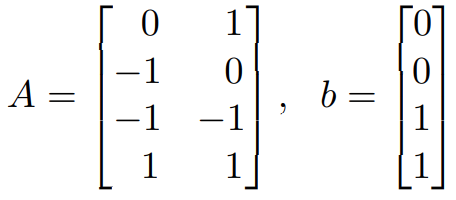

A=[0 1;-1 0;-1 -1;1 1];
b=[0;0;1;1];
P = Polyhedron('A', A, 'b', b)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities   4 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


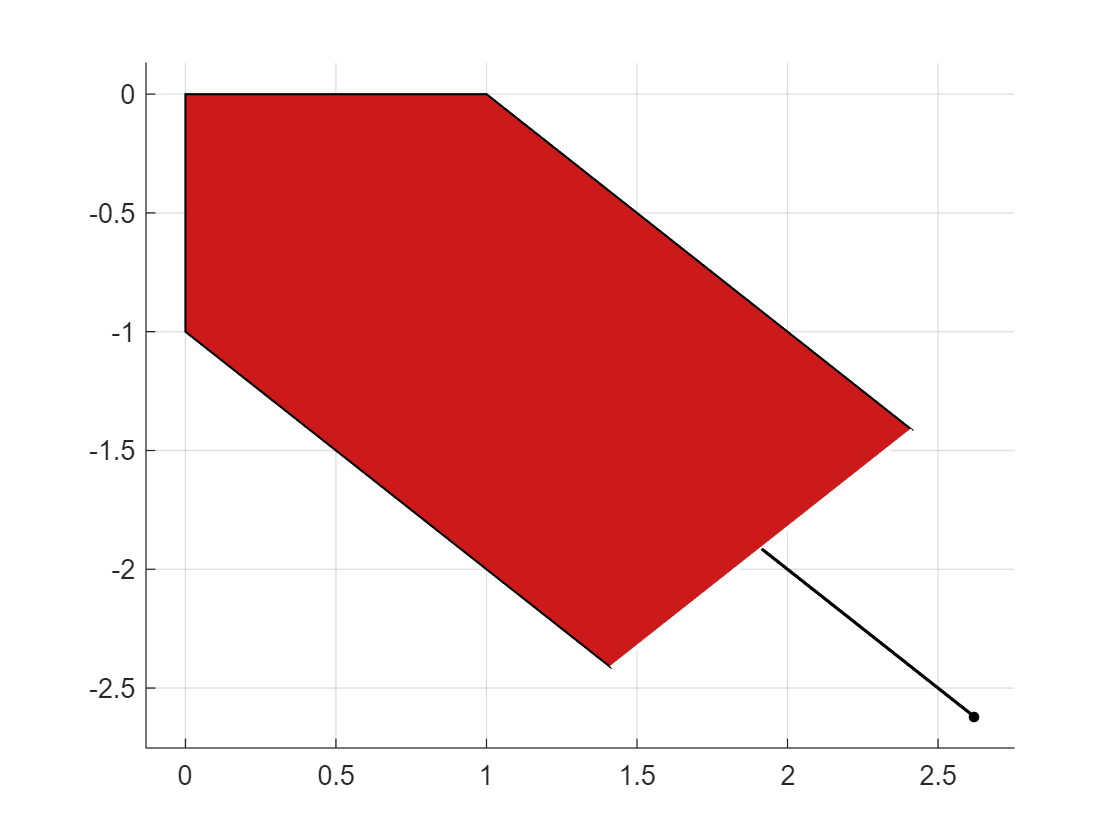

plot(P,'color',[0.8 0.1 0.1],'linewidth',0.8);

H = P.H

H =      0     1     0
    -1     0     0
    -1    -1     1
     1     1     1


V = P.V

V =      0     0
     1     0
     0    -1


V- representation

P = Polyhedron('V', V)

Polyhedron in R^2 with representations:
    H-rep               : Unknown (call computeHRep() to compute)
    V-rep (redundant)   : Vertices   3 | Rays   0
Functions : none


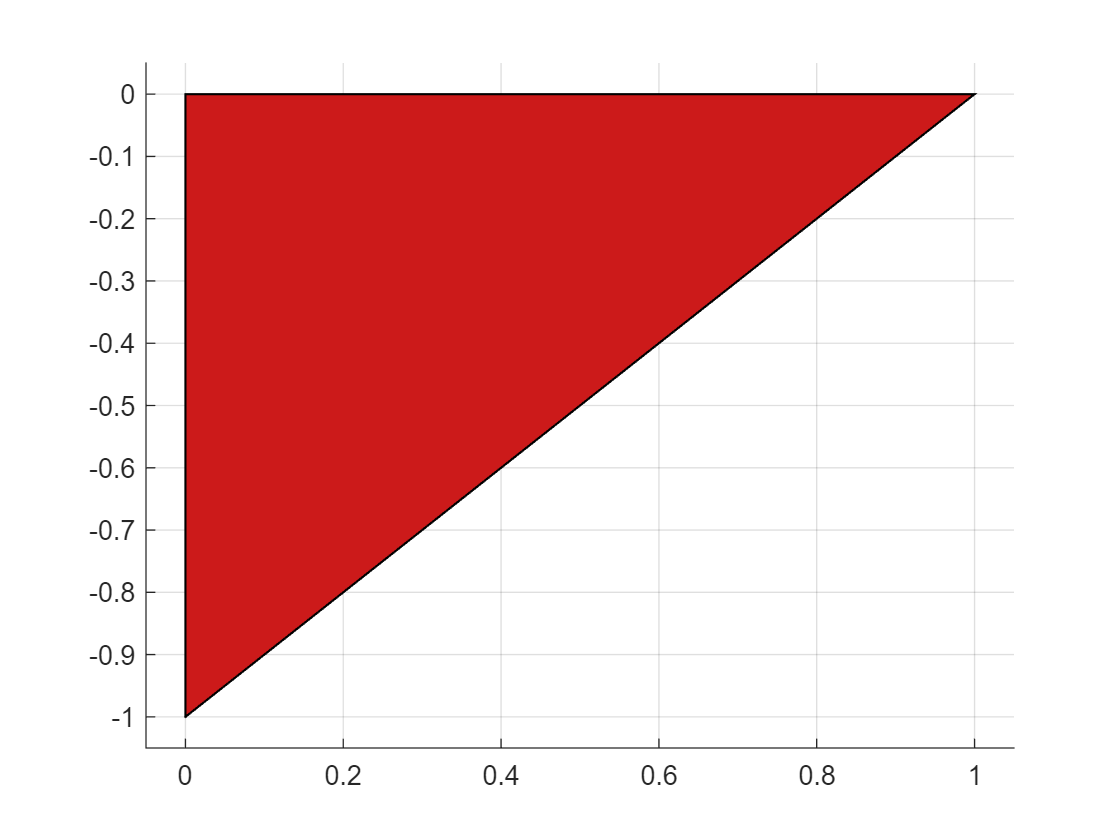

plot(P,'color',[0.8 0.1 0.1],'linewidth',0.8);

H- representation

P = Polyhedron('H', H)

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities   4 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


plot(P,'color',[0.8 0.1 0.1],'linewidth',0.8);

(b) Compute

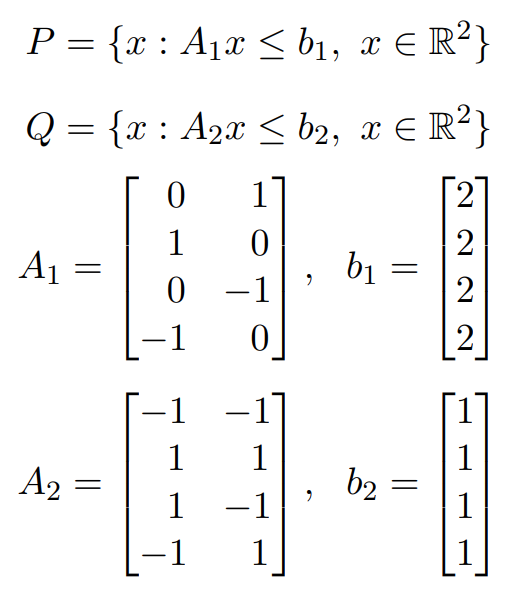

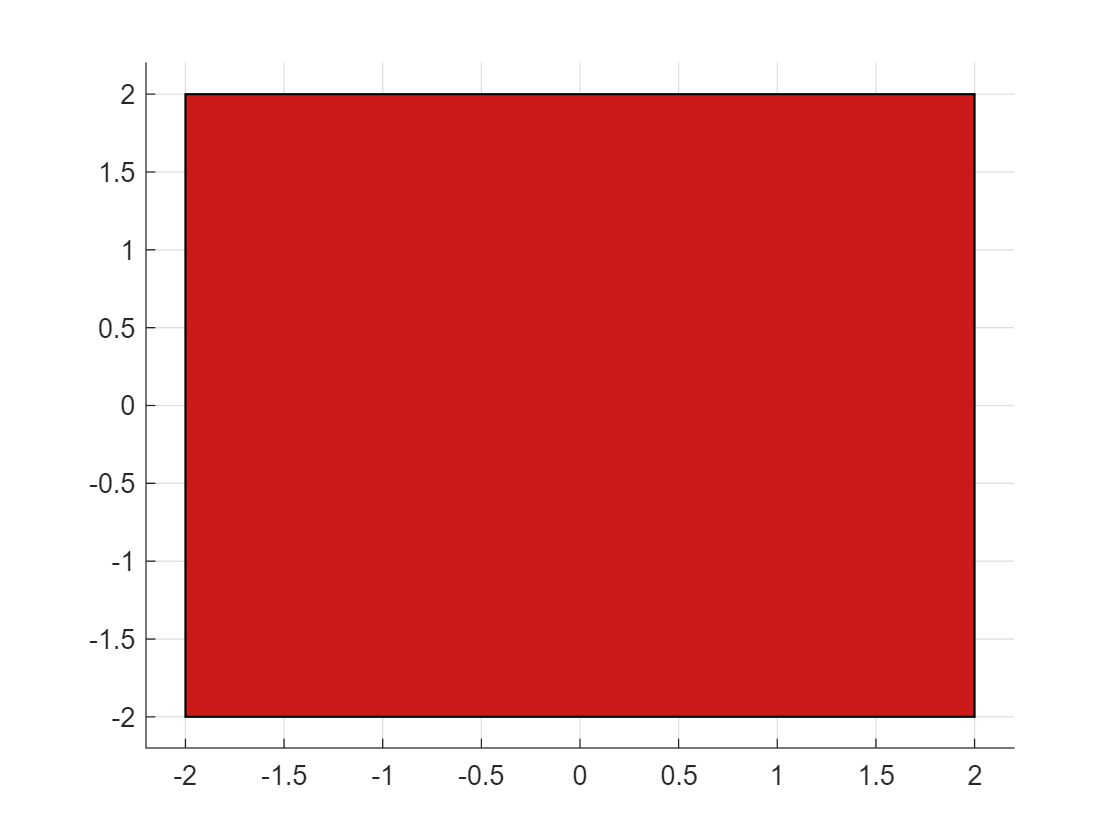

A1 = [0 1;1 0;0 -1;-1 0];
b1 = [2;2;2;2];
A2 = [-1 -1;1 1;1 -1;-1 1];
b2 = [1;1;1;1];

P = Polyhedron('A',A1,'b',b1);
plot(P,'color',[0.8 0.1 0.1],'linewidth',0.8);

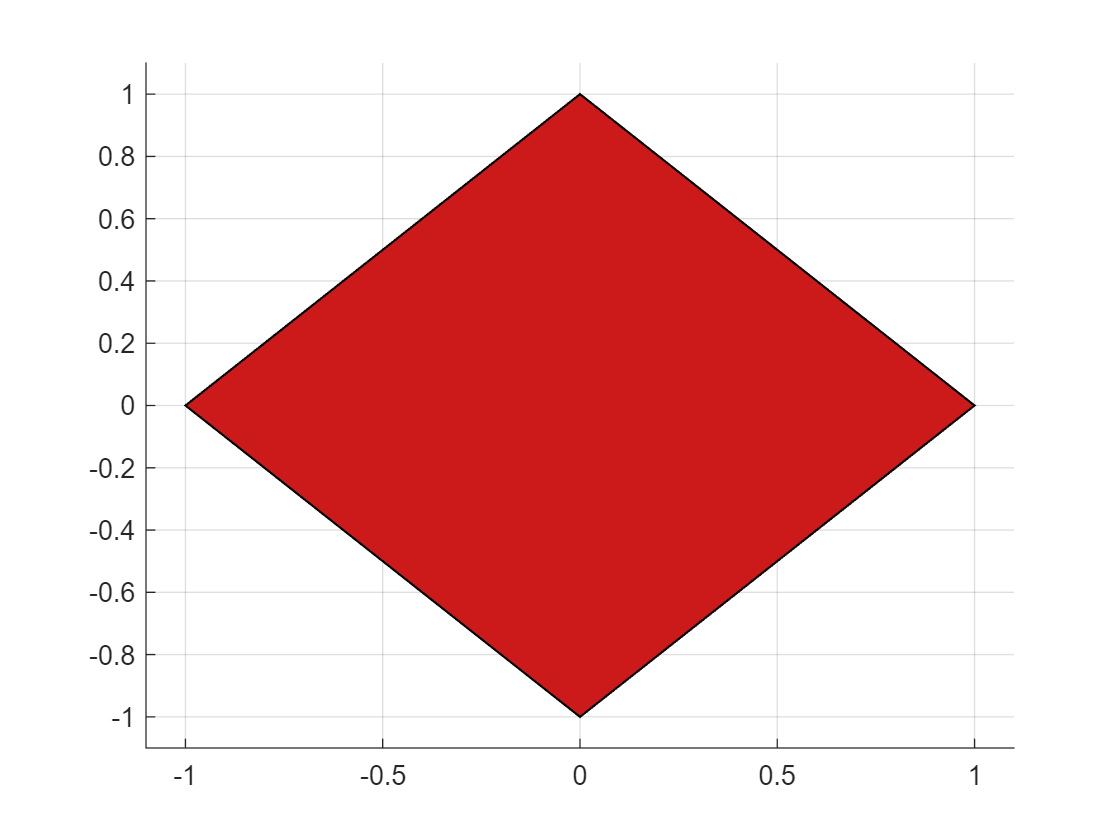

Q = Polyhedron('A',A2,'b',b2);
plot(Q,'color',[0.8 0.1 0.1],'linewidth',0.8);

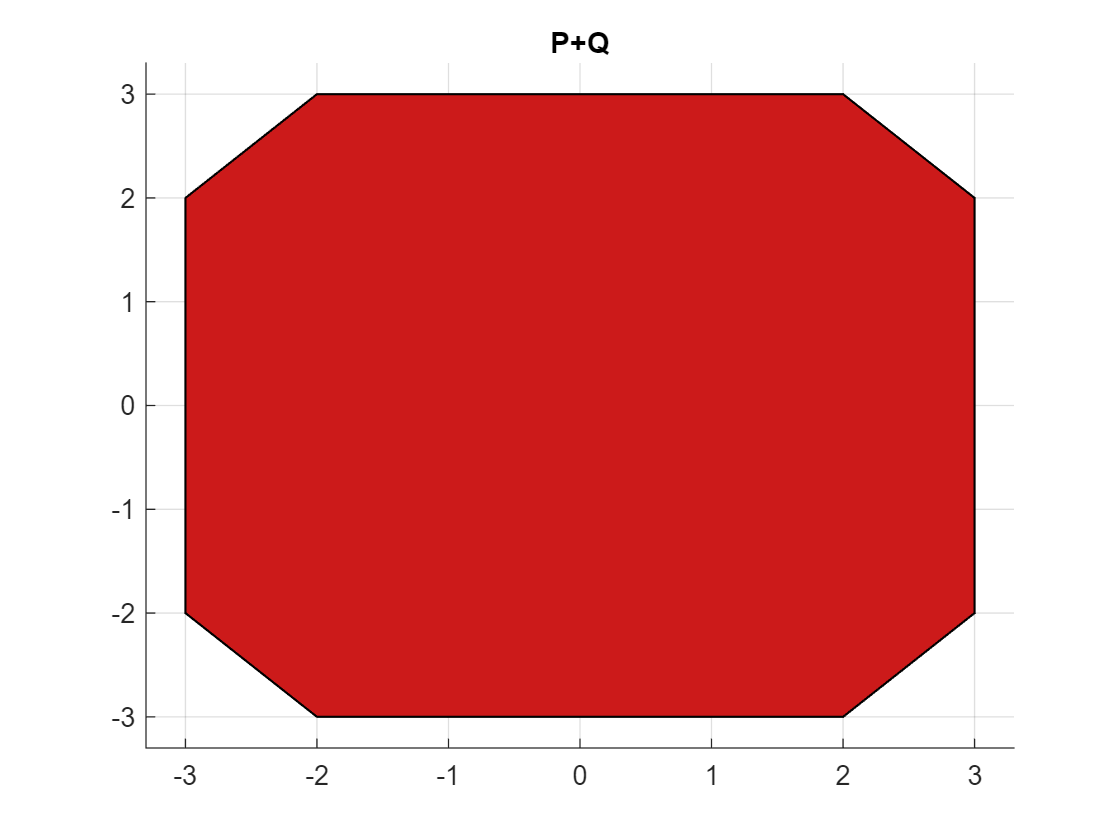

PpQ = plus(P,Q);
PdQ = minus(P,Q);

if(~PdQ.isEmptySet)
    PdQpQ = plus(PdQ, Q);
else
    PdQpQ = Polyhedron();
end

PpQdQ = minus(PpQ, Q);

if(~minus(Q,P).isEmptySet)
    QdPpP = plus(minus(Q,P), P);
else
    QdPpP = Polyhedron();
end
QpPdP = minus(plus(Q,P), P);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
plot(PpQ,'color',[0.8 0.1 0.1],'linewidth',0.8);
title("P+Q")

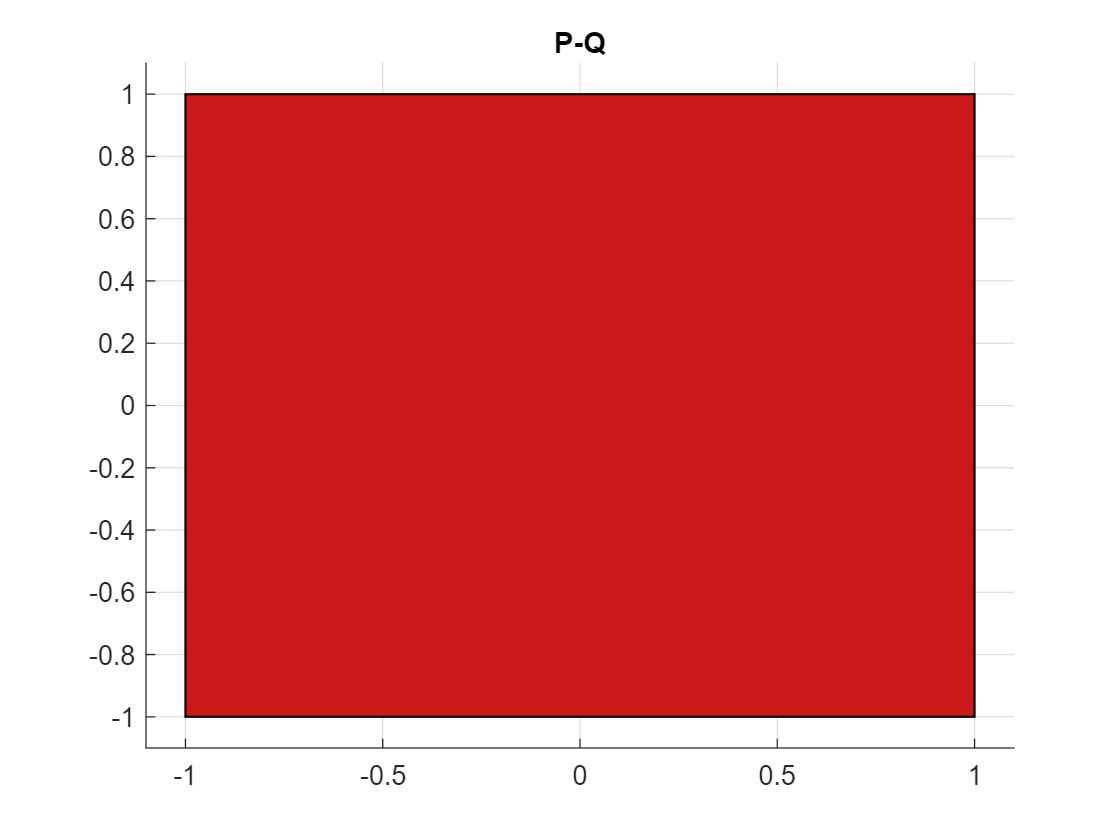

plot(PdQ,'color',[0.8 0.1 0.1],'linewidth',0.8);
title("P-Q")

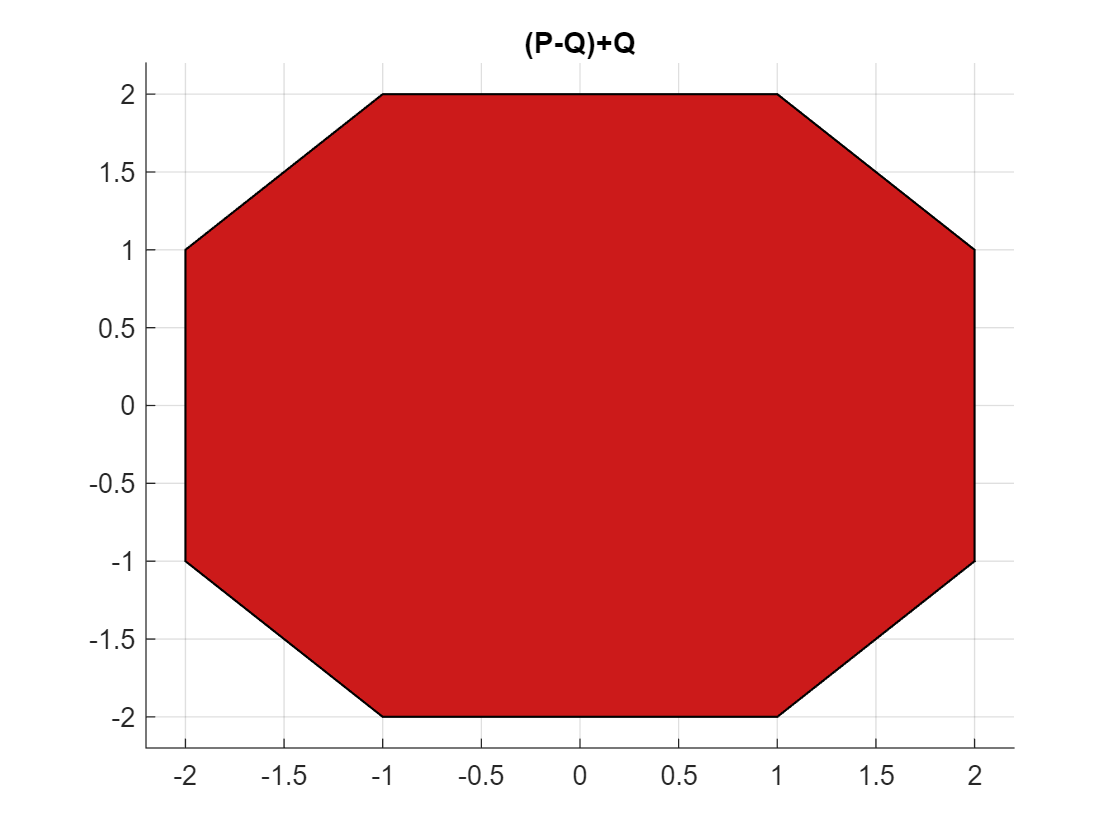

plot(PdQpQ,'color',[0.8 0.1 0.1],'linewidth',0.8);
title("(P-Q)+Q")

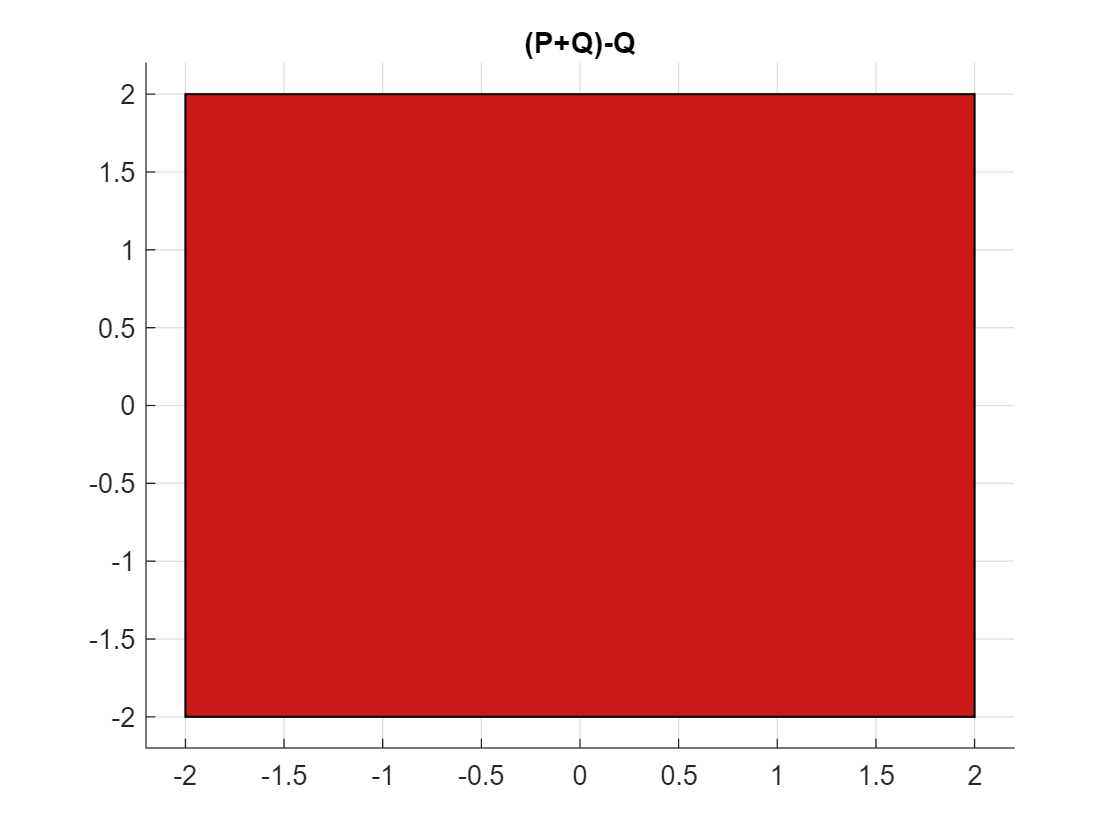

plot(PpQdQ,'color',[0.8 0.1 0.1],'linewidth',0.8);
title("(P+Q)-Q")

if(~QdPpP.isEmptySet)
    plot(QdPpP,'color',[0.8 0.1 0.1],'linewidth',0.8);
    title("(Q-P)+P")
else
    disp("(Q-P)+P is empty!")
end

(Q-P)+P is empty!


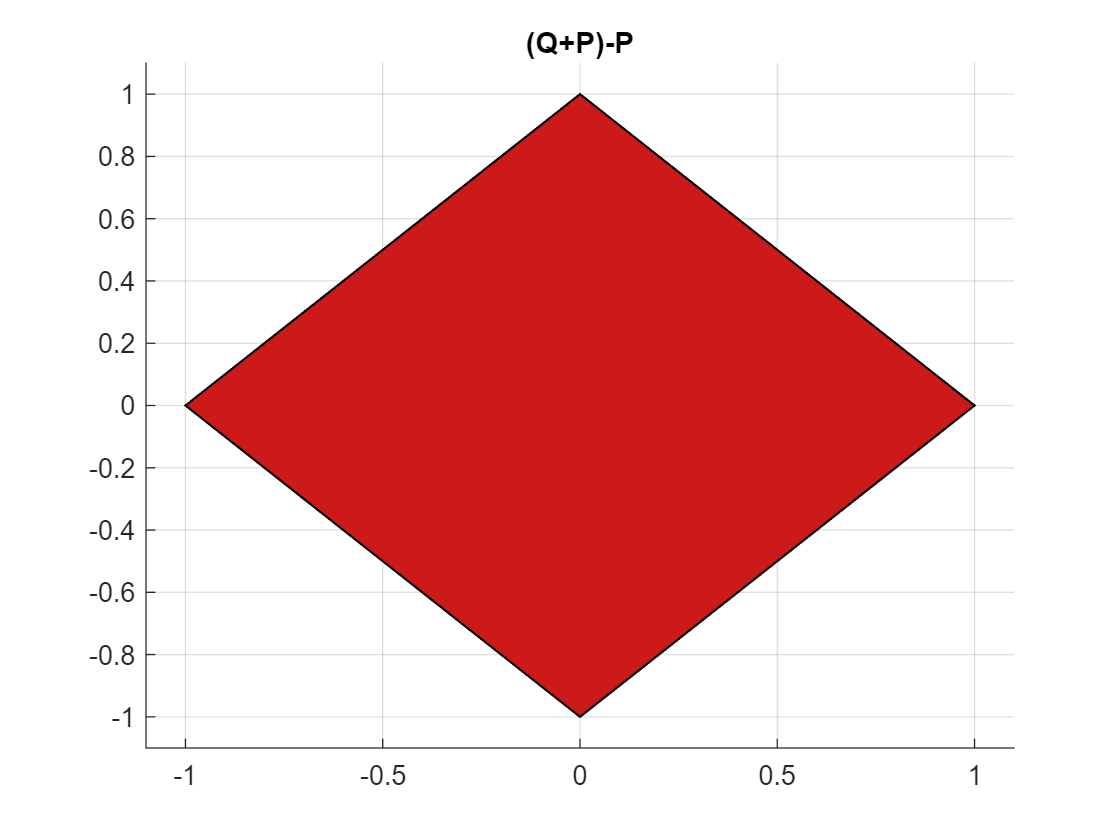


plot(QpPdP,'color',[0.8 0.1 0.1],'linewidth',0.8);
title("(Q+P)-P")

## 2. Forward and backward reachability

A = [0.8 0.4;-0.4 0.8];
model = LTISystem('A',A);

(a) Show that the set S is positively invariant for the system

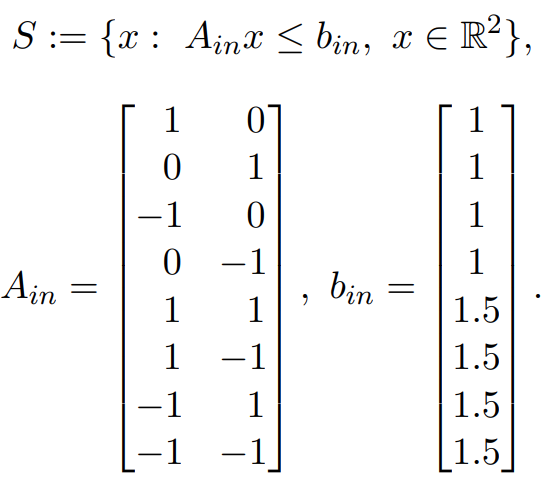

positively invariant set S

Ain = [1 0;0 1;-1 0;0 -1;1 1;1 -1;-1 1;-1 -1];
bin = [1;1;1;1;1.5;1.5;1.5;1.5];
S = Polyhedron('A', Ain, 'b', bin);

Xreach = model.reachableSet('X', S, 'direction', 'forward','N', 200);
if(minus(S,Xreach).isEmptySet)
    disp("S is Xpre. S is the positively invariant set")
else
    disp("S is not the positively invariant set");
end

S is Xpre. S is the positively invariant set


(b) consider the following sysem.

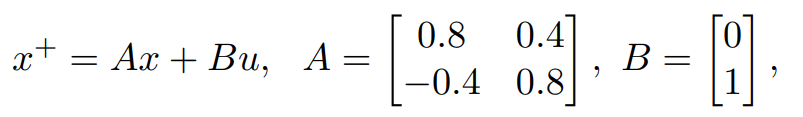

calculate the one-step reachable set from S. Depict S and the reachable set in the same plot.

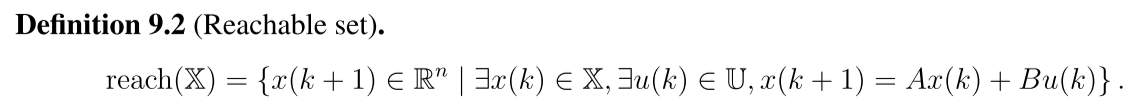

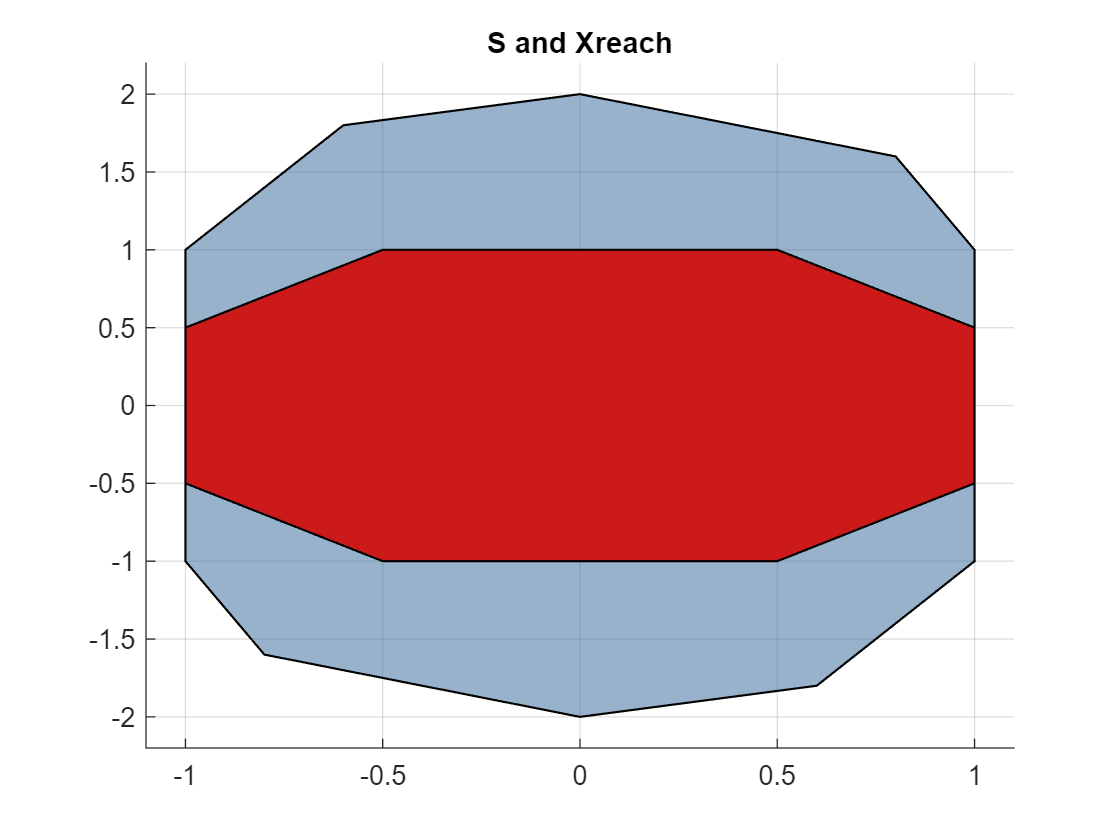

A = [0.8 0.4;-0.4 0.8];
B = [0;1];
model = LTISystem('A',A,'B',B);

% constraints on inputs and states
model.u.min = -1;
model.u.max = 1;
U = Polyhedron('lb',model.u.min,'ub',model.u.max);
% if not using the given function, follow the equation:
% reach(X) = (A mapto X) + (B mapto X)
AtX = affineMap(S,A);
BtX = affineMap(U,B);
Xreach = plus(AtX, BtX);

figure
plot(Xreach,'color',[0.2 0.4 0.6],'linewidth',0.8, 'alpha', 0.5);
hold on
plot(S,'color',[0.8 0.1 0.1],'linewidth',0.8);
title("S and Xreach")

% If using the function
Xreach = model.reachableSet('X', S, 'U', U, 'direction', 'forward','N',1);
figure
plot(Xreach,'color',[0.2 0.4 0.6],'linewidth',0.8, 'alpha', 0.5);
hold on
plot(S,'color',[0.8 0.1 0.1],'linewidth',0.8);
title("S and Xreach")

(c) Calculate one step "Pre" of S for sytem (2).

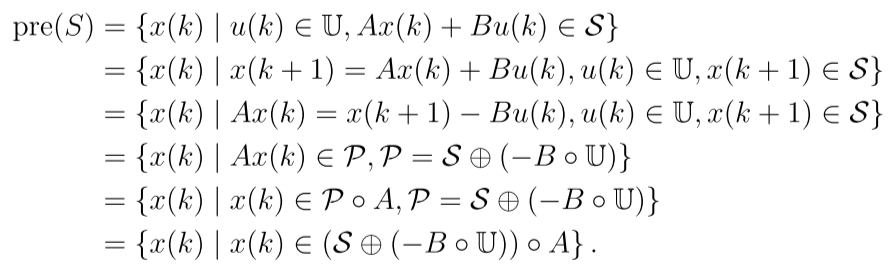

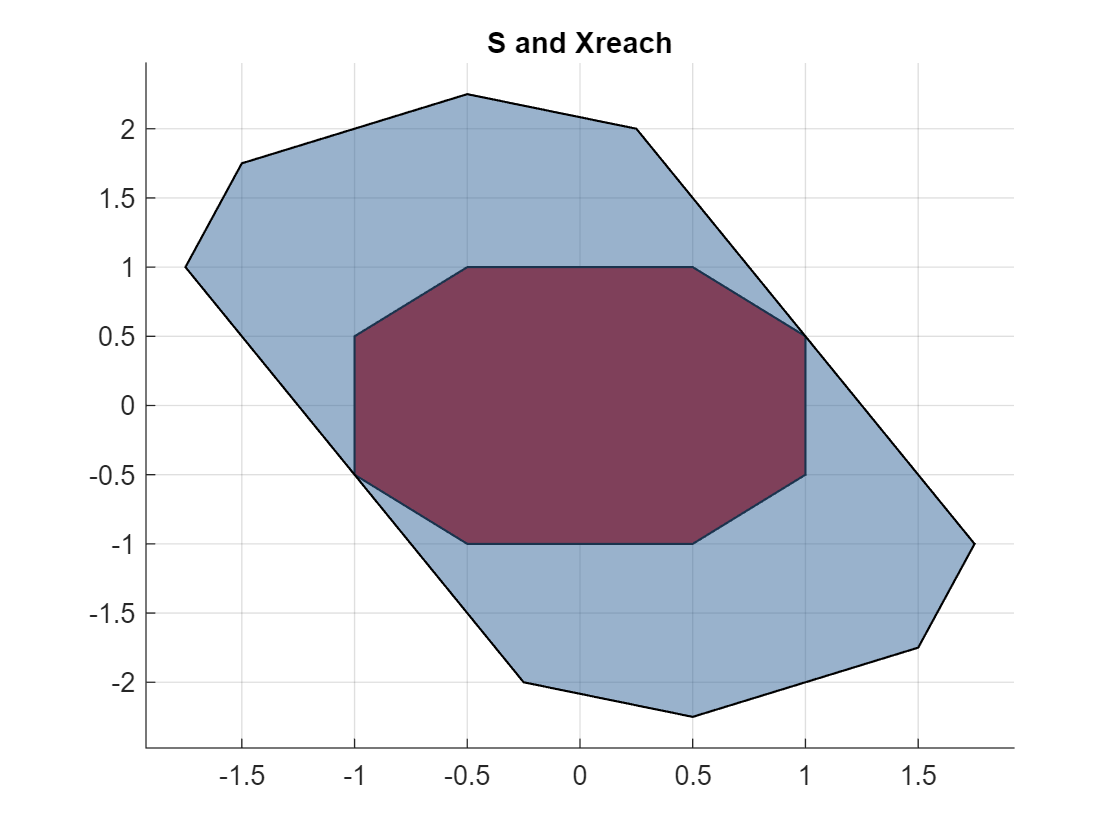

G = S.A;
h = S.b;
Gu = [1;-1];

M1 = [G*A G*B;zeros(2,2) Gu];
b1 = [h;1;1];
tau = Polyhedron('A', M1, 'b', b1);
Xpre = tau.projection(1:2);
figure
plot(S,'color',[0.8 0.1 0.1],'linewidth',0.8);
hold on
plot(Xpre,'color',[0.2 0.4 0.6],'linewidth',0.8, 'alpha', 0.5);
title("S and Xpre, using projection")

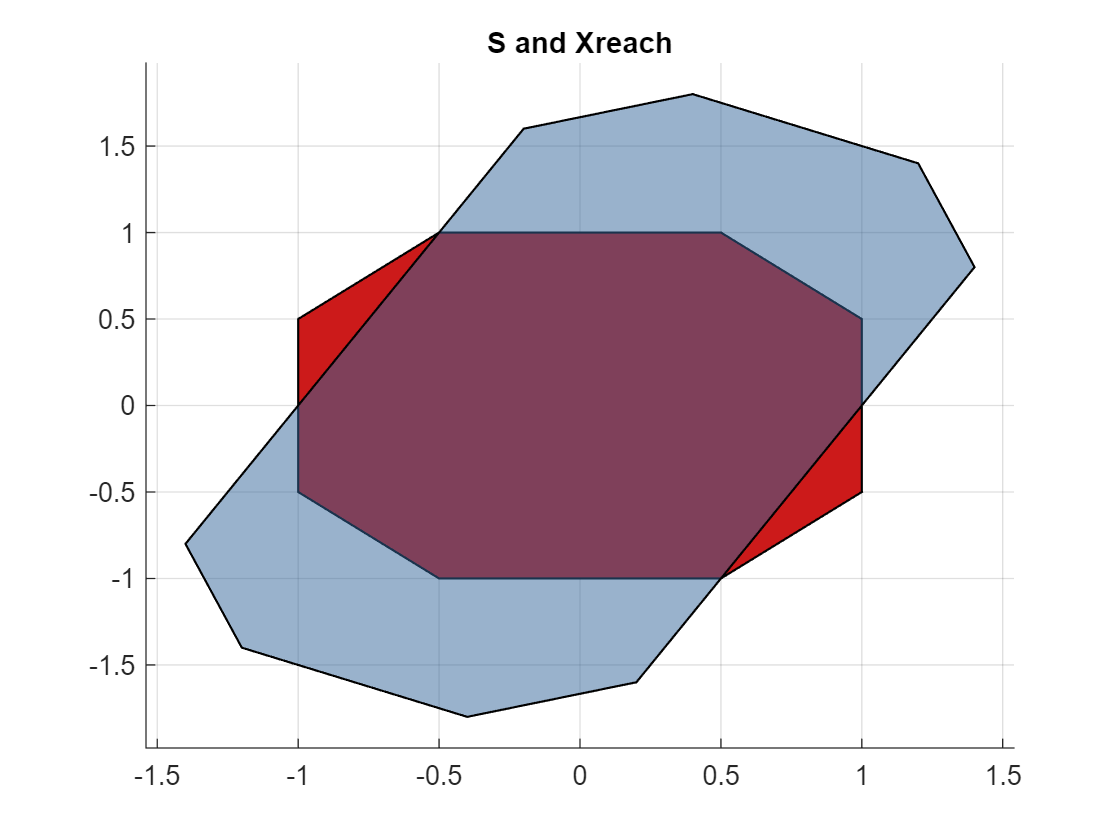

mBtX = affineMap(U,-B);
P = plus(S,mBtX);
Xpre = affineMap(P,A);

figure
plot(S,'color',[0.8 0.1 0.1],'linewidth',0.8);
hold on
plot(Xpre,'color',[0.2 0.4 0.6],'linewidth',0.8, 'alpha', 0.5);
title("S and Xpre, using affineMap")

Xpre= model.reachableSet('X', S, 'U', U, 'direction', 'backward','N', 1);
figure
plot(S,'color',[0.8 0.1 0.1],'linewidth',0.8);
hold on
plot(Xpre,'color',[0.2 0.4 0.6],'linewidth',0.8, 'alpha', 0.5);
title("S and Xpre, using reachableSet")

## 3. Presistent Feasibility

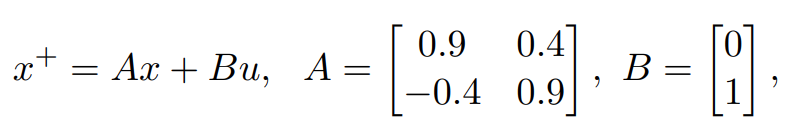

Designded RHC

 

constratints

A = [0.9 0.4;-0.4 0.9];
B = [0;1];
Pf = zeros(2,2);
Q = eye(2);
R = 1;
x0 = [2;0];

model = LTISystem('A',A,'B',B);
model.u.min = -0.1;
model.u.max = 0.1;
model.x.min = [-3;-3];
model.x.max = [3;3];
model.x.penalty = QuadFunction(Q);
model.u.penalty = QuadFunction(R);
model.x.with('terminalPenalty');
model.x.terminalPenalty = QuadFunction(Pf);

% constraint sets represented as polyhedra
X = Polyhedron('lb',model.x.min,'ub',model.x.max);
U = Polyhedron('lb',model.u.min,'ub',model.u.max);

% setting initial condition
X0_set = Polyhedron([2 0]);
model.x.with('initialSet');
model.x.initialSet = X0_set;

(a)  Let $X_f =\textbf{0}_{2 \times 1}$. Find the shortest prediction horzion N that RHC is feasible

Xf = Polyhedron([0 0]);
model.x.with('terminalSet');

model.x.terminalSet = Xf;

% initial guess of prediction horizon
N = 2;

for trial=1:maxIterations
    mpc = MPCController(model,N);
    [~, feasible] = mpc.evaluate(x0);
    if(feasible)
        disp("Shortest prediction horzion N is: ")
            disp(N)
            break
    else
        N = N+1;
    end
end

Shortest prediction horzion N is: 


    26



ctrl = MPCController(model,N);
ctrl.nu

ans = 1

ctrl.nx

ans = 2

(coninue) The following method doesn't use the controller

% terminal set
Xf = Polyhedron([0 0]);
model.x.with('terminalSet');

model.x.terminalSet = Xf;

% find the feasible set
maxIterations  = 30;  % RHC horizon length
XN = Xf;  % initial set
N = 2;
% K(Xf)=pre(K(Xf)) and X, K0(Xf)=Xf
for trial=1:maxIterations
    XN = Xf;  % initial set
    for i=1:N
        back_XN = model.reachableSet('X', XN, 'U', U, 'direction', 'backward','N',1);
        XN = back_XN.intersect(X).minHRep();
    end
    
    if(XN.contains(X0))
        disp("Shortest prediction horzion N is: ")
        disp(N)
        break
    else
        N = N+1;
    end
end

Shortest prediction horzion N is: 


    26



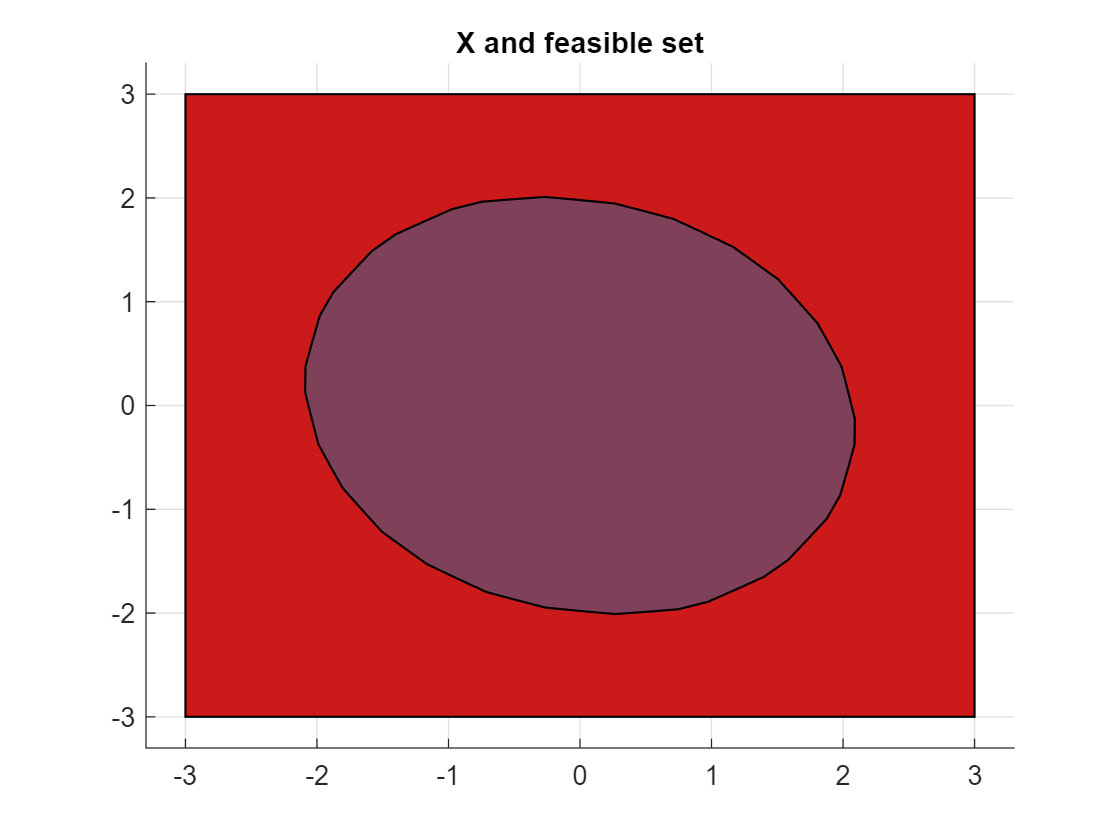

figure
plot(X,'color',[0.8 0.1 0.1],'linewidth',0.8);
hold on
plot(XN,'color',[0.2 0.4 0.6],'linewidth',0.8, 'alpha', 0.5);
title("X and feasible set")

(b) Set N=2, choose $X_f $ as the maximum control invariant set for the system. Is the RHC still feasible until convergence to the origin?

N = 2;
Xf = model.invariantSet();

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...


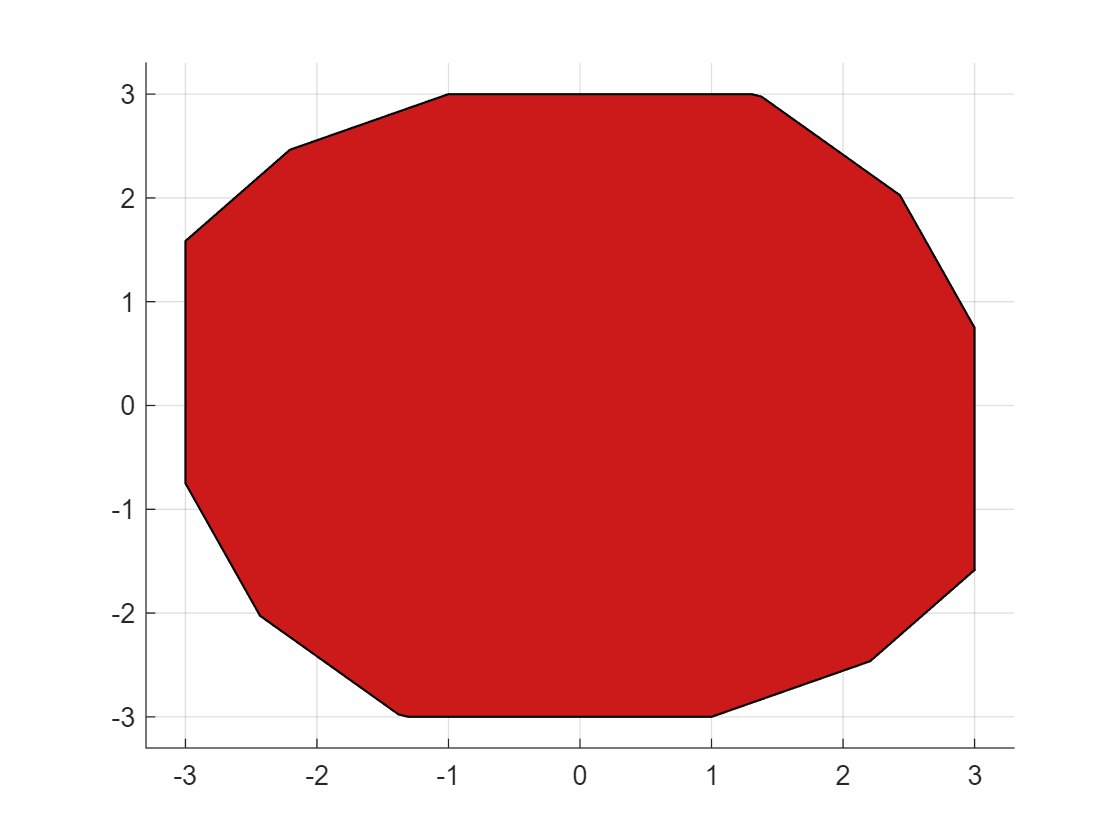

figure
plot(Xf,'color',[0.8 0.1 0.1],'linewidth',0.8);

model.x.with('terminalSet');

model.x.terminalSet = Xf;

mpc = MPCController(model,N);

[u, feasible, openloop] = mpc.evaluate(x0);
feasible

feasible = logical
   1


ctrl = MPCController(model,N);
ctrl.nu

ans = 1

ctrl.nx

ans = 2

(c) Plot the set of feasible initial states for the controllers designed at the previous two points.

Xf = Polyhedron([0 0]);
Xini1 = model.reachableSet('X', Xf, 'U', U, 'direction', 'backward','N',26);

Xf = model.invariantSet();

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...


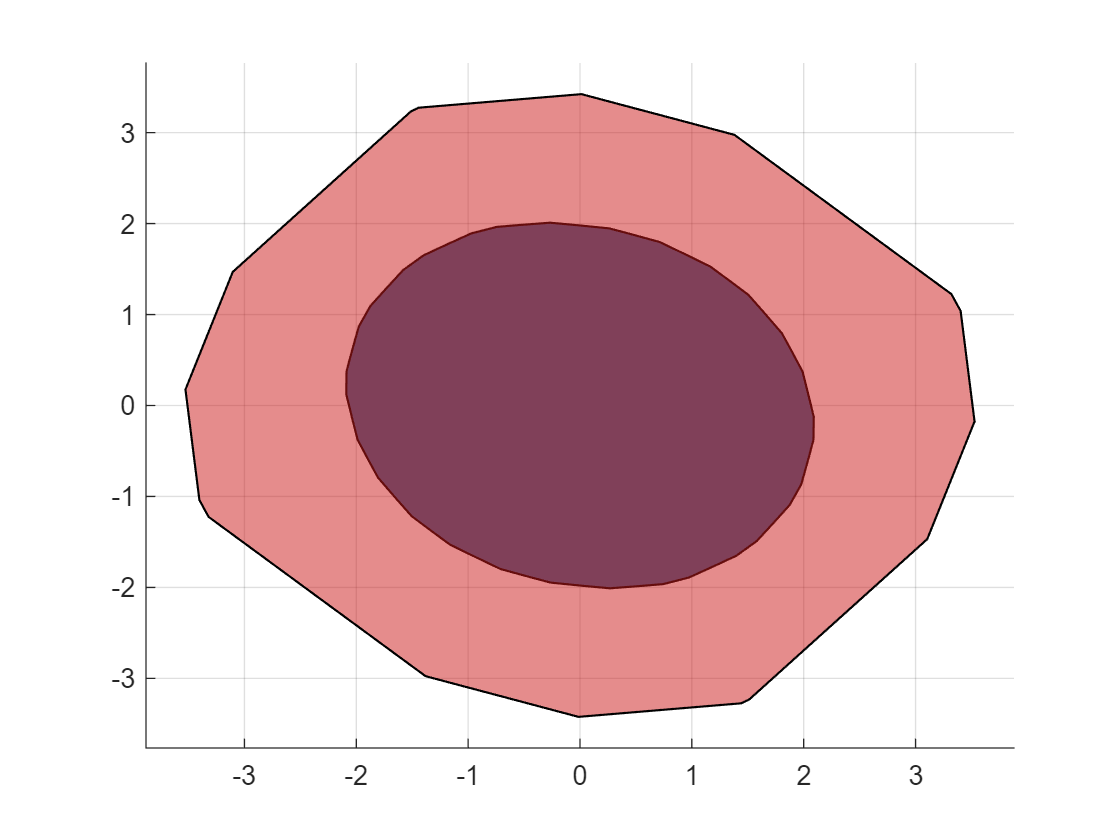

Xini2 = model.reachableSet('X', Xf, 'U', U, 'direction', 'backward','N',2);

figure
plot(Xini1,'color',[0.2 0.4 0.6],'linewidth',0.8);
hold on
plot(Xini2,'color',[0.8 0.1 0.1],'linewidth',0.8,'alpha', 0.5);

title("Xini1 and Xini2(red)")